clear all
close all

x = [1 2 4 7 8];
y = [23 10 4 45 37];
plot(x, y, 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'k')
hold on


for N = 1:5
    G(N,:) = [1, x(N), x(N)^2, x(N)^3, x(N)^4];
end
y = y';
m = inv(G)*y

m =    31.0000
   -0.9167
   -9.7917
    2.9167
   -0.2083


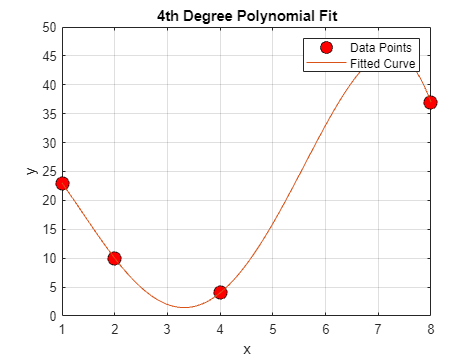


xi = linspace(x(1), x(5), 100); % Increase the number of points for a smoother curve

for i = 1:100
    G_interp(i, :) = [1, xi(i), xi(i)^2, xi(i)^3, xi(i)^4];
end

yi = G_interp*m;

plot(xi, yi); % Plot the fitted curve
xlabel('x');
ylabel('y');
title('4th Degree Polynomial Fit');
legend('Data Points', 'Fitted Curve');
grid on;

hold off;